close all,
clear all,
%% ========================================================================
% PIPELINE COMPLETO: COVARIANCE–PCA → MANOVA → CARGAS & VISUALIZACIONES & CORRELACIONES
% Fichero: Five_times_Kinematics_HT_Query_SIN_OUTLIERS_con tres_variables.xlsx
% ========================================================================

%% 0) Carga de datos y definición de factores
Tdata = readtable('Five_times_Kinematics_HT_Query_final.xlsx', ...
                  'VariableNamingRule','preserve');

% Factores entre sujetos
AgeGroup  = categorical(Tdata.AgeGroup);    % e.g. '60-67','68-75'
BMI_Value = categorical(Tdata.BMI_Value);   % e.g. 'High','Low'
GroupName = categorical(Tdata.GroupName);   % e.g. 'Conservador','Artroplástia'

% Extrae sólo las medidas cinemáticas (columnas 5 en adelante)
numericVars = Tdata.Properties.VariableNames(5:end);
X_lin = Tdata{:, numericVars}';              % → [features × n_obs]

%% 1) “Quadratic kernel” + PCA
X = X_lin;
lin_dim = size(X,1);

% a) cuadrados
for i = 1:lin_dim
    X(lin_dim+i,:) = X(i,:).^2;
end

% b) interacciones adyacentes (skip múltiplos de 5)
quad_dim = size(X,1);
for i = 1:lin_dim
    if mod(i,5)==0, continue; end
    X(quad_dim+i,:) = X(i,:).*X(i+1,:);
end

% c) eliminar filas todas cero
X = X(any(X~=0,2),:);

% d) quitar última fila (sobrante)
X(end,:) = [];

% PCA
S = cov(X');
[V,D] = eig(S);
eVals  = sort(diag(D),'descend');
cumVar = cumsum(eVals)/sum(eVals);
p = find(cumVar>=0.95,1,'first');            % nº de PCs para 95%

[~, idx] = sort(diag(D),'descend');
Vp = V(:, idx(1:p));                          % loadings [features × p]

n = size(X,2);
Xc = X - mean(X,2);
Y  = Vp' * Xc;                                % scores [p × n]

%% 2) MANOVA global
Y_scores = Y';                                % [n × p]
pcNames  = arrayfun(@(k) sprintf('PC%d',k), 1:p,'uni',false);
Tpc = array2table(Y_scores,'VariableNames',pcNames);
Tpc.Age       = AgeGroup;
Tpc.BMI       = BMI_Value;
Tpc.Treatment = GroupName;

rm = fitrm(Tpc, sprintf('PC1-PC%d ~ Age*BMI*Treatment',p));
disp('=== MANOVA global ===');

=== MANOVA global ===


disp(manova(rm));

     Within          Between         Statistic      Value         F         RSquare     df1    df2     pValue 
    ________    _________________    _________    _________    ________    _________    ___    ___    ________

    Constant    (Intercept)          Pillai       0.0054812    0.037477    0.0054812     5     34      0.99917
    Constant    (Intercept)          Wilks          0.99452    0.037477    0.0054812     5     34      0.99917
    Constant    (Intercept)          Hotelling    0.0055114    0.037477    0.0054812     5     34      0.99917
    Constant    (Intercept)          Roy          0.0055114    0.037477    0.0054812     5     34      0.99917
    Constant    Age        


%% 3) ANOVA univariados y post-hoc (por PC)
groupNames = {'AgeGroup','BMI_Value','GroupName'};
factors    = {AgeGroup,BMI_Value,GroupName};

disp('=== ANOVA univariados (ranova) ===');

=== ANOVA univariados (ranova) ===


disp(ranova(rm));

                                SumSq       DF       MeanSq         F          pValue      pValueGG     pValueHF     pValueLB
                              __________    ___    __________    ________    __________    _________    _________    ________

    (Intercept):Time          2.7625e+05      5         55251    0.072841        0.9962      0.91635      0.92378      0.7887
    Age:Time                  6.3167e+06      5    1.2633e+06      1.6655       0.14481       0.1985      0.19716     0.20465
    BMI:Time                  2.3713e+07      5    4.7426e+06      6.2525    2.1505e-05    0.0040649    0.0035003    0.016833
    Treatment:Time           


for k = 1:p
    fprintf('\n--- PC %d ---\n',k);
    dataPC = Y(k,:)';
    [~,~,stats] = anovan(dataPC,factors, ...
                         'model','interaction', ...
                         'varnames',groupNames, ...
                         'display','off');
    for f = 1:numel(groupNames)
        fprintf('\nPost-hoc %s:\n',groupNames{f});
        [c,~] = multcompare(stats, ...
                            'Dimension',f, ...
                            'CType','bonferroni', ...
                            'Display','off');
        T = array2table(c, ...
            'VariableNames',{'G1','G2','Lower','MeanDiff','Upper','pValue'});
        disp(T);
    end
end


--- PC 1 ---



Post-hoc AgeGroup:


    G1    G2     Lower     MeanDiff    Upper     pValue 
    __    __    _______    ________    ______    _______

    1     2     -1803.9    -741.98     319.92    0.16549




Post-hoc BMI_Value:


    G1    G2     Lower     MeanDiff     Upper      pValue 
    __    __    _______    ________    _______    ________

    1     2     -2653.1    -1575.5     -497.83    0.005251




Post-hoc GroupName:


    G1    G2     Lower     MeanDiff    Upper     pValue 
    __    __    _______    ________    ______    _______

    1     2     -1723.9    -649.51     424.91    0.22876




--- PC 2 ---



Post-hoc AgeGroup:


    G1    G2     Lower     MeanDiff    Upper     pValue 
    __    __    _______    ________    ______    _______

    1     2     -538.79    -4.7775     529.23    0.98565




Post-hoc BMI_Value:


    G1    G2     Lower     MeanDiff    Upper     pValue 
    __    __    _______    ________    ______    _______

    1     2     -639.31     -97.38     444.55    0.71822




Post-hoc GroupName:


    G1    G2     Lower     MeanDiff    Upper     pValue 
    __    __    _______    ________    ______    _______

    1     2     -564.18    -23.868     516.44    0.92926




--- PC 3 ---



Post-hoc AgeGroup:


    G1    G2     Lower     MeanDiff    Upper     pValue 
    __    __    _______    ________    ______    _______

    1     2     -479.53    -127.77     223.99    0.46691




Post-hoc BMI_Value:


    G1    G2     Lower     MeanDiff    Upper     pValue 
    __    __    _______    ________    ______    _______

    1     2     -196.26     160.72     517.69    0.36807




Post-hoc GroupName:


    G1    G2     Lower     MeanDiff    Upper     pValue 
    __    __    _______    ________    ______    _______

    1     2     -327.73     28.18      384.09    0.87359




--- PC 4 ---



Post-hoc AgeGroup:


    G1    G2     Lower     MeanDiff    Upper     pValue 
    __    __    _______    ________    ______    _______

    1     2     -258.02    -51.674     154.67    0.61534




Post-hoc BMI_Value:


    G1    G2     Lower     MeanDiff    Upper     pValue 
    __    __    _______    ________    ______    _______

    1     2     -288.85    -79.444     129.97    0.44749




Post-hoc GroupName:


    G1    G2    Lower     MeanDiff    Upper      pValue  
    __    __    ______    ________    ______    _________

    1     2     103.02     311.8      520.59    0.0044345




--- PC 5 ---



Post-hoc AgeGroup:


    G1    G2     Lower     MeanDiff    Upper     pValue 
    __    __    _______    ________    ______    _______

    1     2     -151.55     32.179     215.91    0.72505




Post-hoc BMI_Value:


    G1    G2     Lower     MeanDiff    Upper     pValue 
    __    __    _______    ________    ______    _______

    1     2     -176.24     10.21      196.66    0.91237




Post-hoc GroupName:


    G1    G2     Lower     MeanDiff    Upper    pValue
    __    __    _______    ________    _____    ______

    1     2     -236.19    -50.298     135.6    0.5873




--- PC 6 ---



Post-hoc AgeGroup:


    G1    G2     Lower     MeanDiff    Upper     pValue 
    __    __    _______    ________    ______    _______

    1     2     -71.874     77.53      226.93    0.30035




Post-hoc BMI_Value:


    G1    G2     Lower     MeanDiff    Upper     pValue 
    __    __    _______    ________    ______    _______

    1     2     -223.55    -71.929     79.692    0.34318




Post-hoc GroupName:


    G1    G2     Lower     MeanDiff    Upper     pValue 
    __    __    _______    ________    ______    _______

    1     2     -249.91     -98.74     52.427    0.19414




%% 4) Exploración de cargas: PC1 y PC4
%% 4) Exploración de cargas: PC1 y (si existe) PC4 con TODAS las variables
origNames = numericVars;

% Generar nombres para cuadráticas
quadNames = strcat(numericVars, '^2');

% Generar nombres para interacciones adyacentes (excepto múltiplos de 5)
interNames = {};
for i = 1:(length(numericVars)-1)
    if mod(i,5) == 0, continue; end
    interNames{end+1} = [numericVars{i} '*' numericVars{i+1}];
end

% Concatenar todos los nombres y asegurar columna
allNames = [origNames, quadNames, interNames]';
allNames = allNames(:);  

% Cargas de todas las variables
loadings = Vp;
nVars = size(loadings, 1);

% Alinear etiquetas con filas de loadings
if length(allNames) > nVars
    allNames = allNames(1:nVars);
elseif length(allNames) < nVars
    extra = arrayfun(@(k) sprintf('ExtraVar_%d', k), 1:(nVars-length(allNames)), 'Uni', false)';
    allNames = [allNames; extra];
end

topN = 10;  % cuántas cargas mostrar

% --- PC1 ---
[~, order1] = sort(abs(loadings(:,1)), 'descend');
feat1 = allNames(order1(1:topN));              % 10×1 cell
vals1 = loadings(order1(1:topN), 1);           % 10×1 double
fprintf('\nTop %d cargas en PC1 (todas las variables):\n', topN);


Top 10 cargas en PC1 (todas las variables):


disp(table(feat1, vals1, ...
    'VariableNames', {'Feature', 'LoadingPC1'}));

            Feature            LoadingPC1
    _______________________    __________

    {'1_ aSPFEM^2'        }      0.33927 
    {'1_ aSPFEM*2_ aSPFEM'}      0.32291 
    {'4_ aSPFEM^2'        }      0.31838 
    {'3_ aSPFEM^2'        }      0.31453 
    {'4_ aSPFEM*5_ aSPFEM'}      0.31434 
    {'2_ aSPFEM*3_ aSPFEM'}      0.31098 
    {'5_ aSPFEM^2'        }      0.31027 
    {'2_ aSPFEM^2'        }       0.3073 
    {'1_ aHPFEM^2'        }     -0.24397 
    {'1_ aHPFEM*2_ aHPFEM'}     -0.18422 




% --- PC4 (si existe) ---
if p >= 4
    [~, order4] = sort(abs(loadings(:,4)), 'descend');
    feat4 = allNames(order4(1:topN));          % 10×1 cell
    vals4 = loadings(order4(1:topN), 4);       % 10×1 double
    fprintf('\nTop %d cargas en PC4 (todas las variables):\n', topN);
    disp(table(feat4, vals4, ...
        'VariableNames', {'Feature', 'LoadingPC4'}));
else
    warning('Sólo se obtuvieron %d PCs; no hay PC4 para explorar cargas.', p);
end


Top 10 cargas en PC4 (todas las variables):


              Feature              LoadingPC4
    ___________________________    __________

    {'5_ aKFEM^2'             }     -0.76636 
    {'4_ aKFEM*5_ aKFEM'      }     -0.25964 
    {'5_ aHPFEM^2'            }      0.19687 
    {'4_ aHPFEM*5_ aHPFEM'    }      0.18382 
    {'4_ aHPFEM^2'            }      0.16414 
    {'5_ aSHROTOFFM*1_ aSPFEM'}      -0.1569 
    {'5_ aKIEM*1_ aHPFEM'     }      0.14255 
    {'4_ aPTILTM^2'           }      0.10269 
    {'3_ aPTILTM*4_ aPTILTM'  }      0.10065 
    {'3_ aPTILTM^2'           }     0.098084 



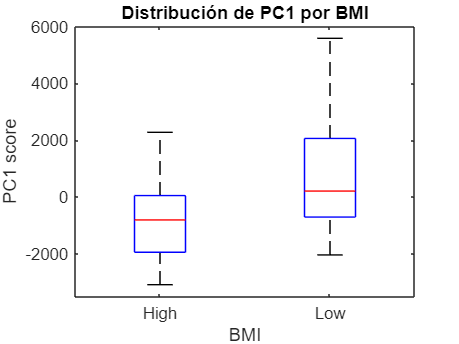


%% 5) Visualizaciones
% a) Boxplot PC1 por nivel de BMI
figure;
boxplot(Y(1,:)', BMI_Value);
xlabel('BMI'); ylabel('PC1 score');
title('Distribución de PC1 por BMI');

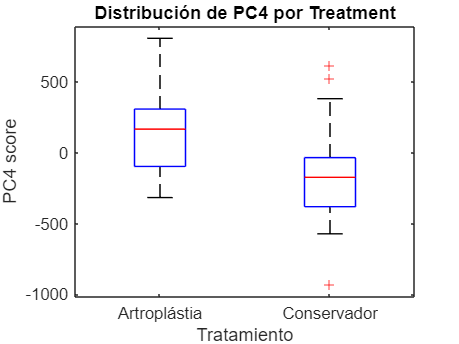


% b) Boxplot PC4 por tratamiento
figure;
boxplot(Y(4,:)', GroupName);
xlabel('Tratamiento'); ylabel('PC4 score');
title('Distribución de PC4 por Treatment');